# Constants

clear;
profile on

## Right Image

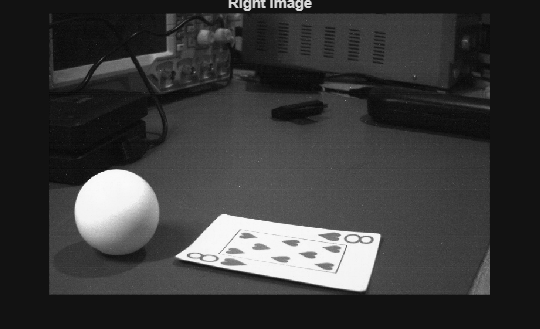

rightImage = imread("images\right9.jpg");
rightGray  = rgb2gray(rightImage);

figure(1);
imshow(rightGray); hold on;
[centersR, radiiR, metricR] = imfindcircles(rightGray, [15 100]);
viscircles(centersR, radiiR, 'EdgeColor', 'red');   
title("Right image");

%[~, iR] = max(metricR); % use the "best" circle
uR = centersR(centersR, 1)

Index in position 2 exceeds array bounds.

vR = centersR(centersR, 2)

## Left Image


leftImage = imread("images\left7.jpg");
leftGray  = rgb2gray(leftImage);

figure(2);
imshow(leftGray); hold on;
[centersL, radiiL, metricL] = imfindcircles(leftGray, [15 100]);
viscircles(centersL, radiiL, 'EdgeColor', 'blue');
title("Left image");
[~, iL] = max(metricL); % use the "best" circle
uL = centersL(iL, 1)
vL = centersL(iL, 2)

## Constants

% default values from LAB document
b = 50; % baseline [mm]
px = 0.006; % pixel size [mm]
f = 6; % focal length [mm]
fpx = f / px; % focal length [px]
xNumPix = size(leftGray, 2) % num pix x [px]
yNumPix = size(leftGray, 1) % num pix y [px]
cxOrigin = xNumPix/2; % Origin camera x center [px]
cyOrigin = yNumPix/2; % Origin camera y center [px]
cxBaseline = xNumPix/2; % Camera baseline distance x center [px]
cyBaseline = yNumPix/2 ; % Camera baseline distance y center [px]

## 3D Centroid

d = uL - uR % disparity [px]

z = (fpx * b) / d % depth [mm]
x = (uL - cxOrigin) * z / fpx % x cord [mm]
y = -(vL - cyOrigin) * z / fpx % y cord [mm]

## Close Profile and display runtime

profile off
p = profile('info');
totalTime = p.FunctionTable(1).TotalTime; % Total time of the top-level function
totalTime = totalTime % total time in seconds
profile viewer